Practical Practice 13 - Ordinary Differential Equation

Write a script file that solves the following ODE using Euler’s method from t = 0 to 3 with a step size of h = 0.5 where y(0) = 1. Plot the results.

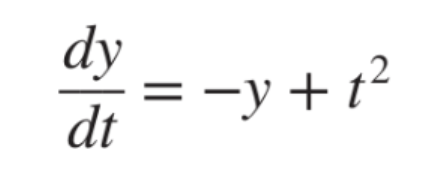

% Euler's method equation
% yi+1 = yi + f(ti, yi)h
syms y t
eq = -y + t^2;
y = eulerOde(1, 0.5, 0, 3, eq);

y =     4.4922         0         0         0         0         0         0
    1.0000    0.5000    0.3750    0.6875    1.4688    2.7344    4.4922


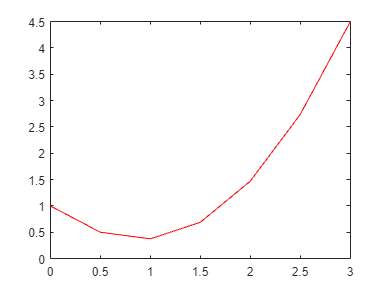

t = 0:0.5:3;
plot(t, y(2,:), 'r')

disp(y(1))

    4.4922



Repeat Question 1 using Heun’s method without iteration.

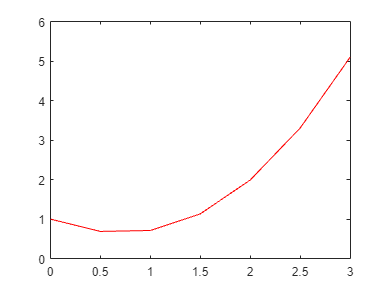

% using function for Heun's without iteration
y1 = heunsOde(1, 0.5, 0, 3, eq);

% set the t as the initial and final with steps
t = 0:0.5:3;

% Plot and display
plot(t, y1(2,:), 'r')

disp(y1(1))

    5.0971



Repeat Question 1 using Heun’s method with iteration until the approximate error is less than 0.1%.

syms y t
exeq = 4 * exp(0.8 * t) - 0.5 * y;
HeunIterativeMethod(1, 0.5, 0, 3, eq, 0.1)

ans = 1

Repeat Question 1 using 4th order RK

rungeKutta4(1, 0.5, 0, 3, eq)

ans =     1.0000    0.6439    0.6329    1.0279    1.8659    3.1693    4.9517


Convert the following 2nd order ODE into a system of 1st order ODEs and then write a script file that solves it from t = 0 to 10 using Euler’s method using a step size of h = 0.1.  The initial conditions are y(0) = y’(0) = 1. Plot the results.

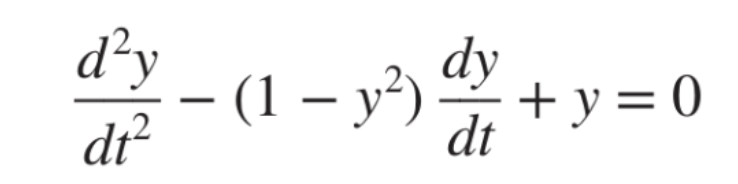

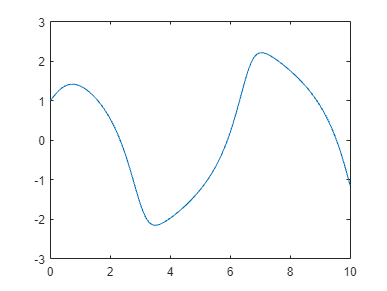

% assuming u = dy/dt, v = t
% u' = d2y/d2t = (1 - y^2) * u + y, v' = dy/dt = u
% Therefore the 2 1st order ODE is
% u' = (1 - y^2) * u + y
% v' = u

% Step 1: Setup
h = 0.1;
t = 0:h:10;
x1 = 1;
x2 = 1;
func1 = @(t,x1,x2) x2;
func2 = @(t,x1,x2) ((1 - x1.^2) .* x2) - x1;

for i = 1:length(t)-1
   x1(i+1) = x1(i) + h.*( func1(t(i) , x1(i) , x2(i)) );
   x2(i+1) = x2(i) + h.*( func2(t(i) , x1(i) , x2(i)) );
end
plot(t,x1)    % Original variable against time.

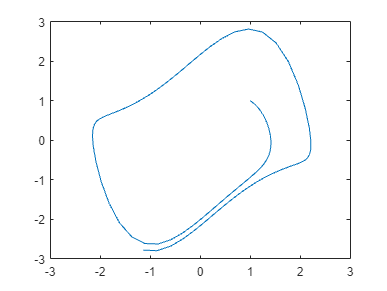

plot(x1,x2)   % Phase diagram of the 2 variables.

A pond drains through a pipe as shown in the figure on the next page. Under a number of simplifying assumptions, the following differential equation describes how depth changes with time:

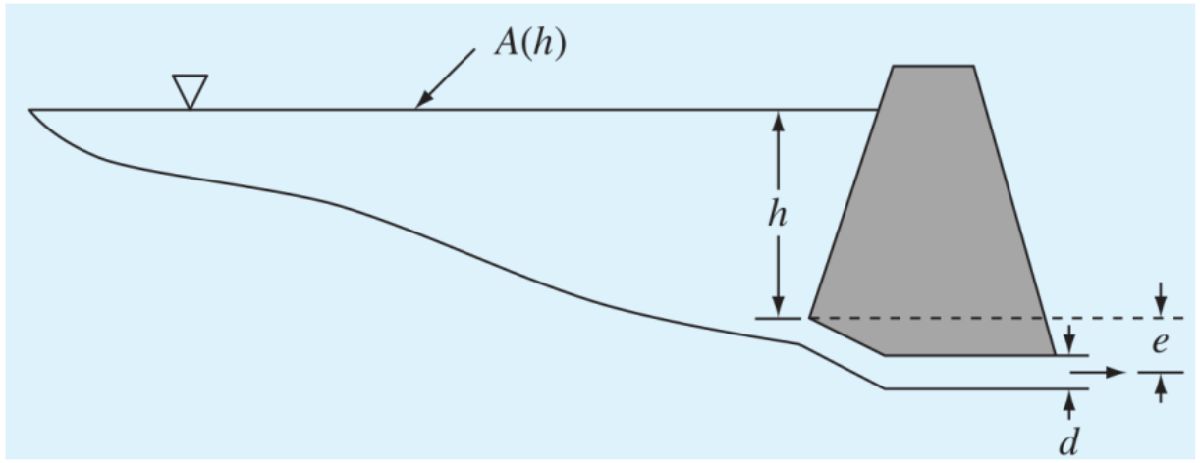

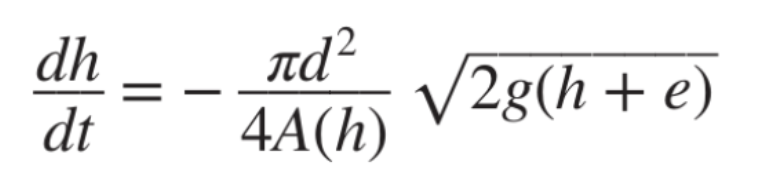

where *h* = depth (m), *t* = time (s), *d* = pipe diameter (m), *A*(*h*) = pond surface area as a function of depth (m2), *g* = gravitational constant (= 9.81 m/s2), and *e* = depth of pipe outlet below the pond bottom (m). Based on the following area-depth table, solve this differential equation to determine how long it takes for the pond to empty, given that *h*(0) = 6 m, *d* = 0.25 m, *e* = 1 m.

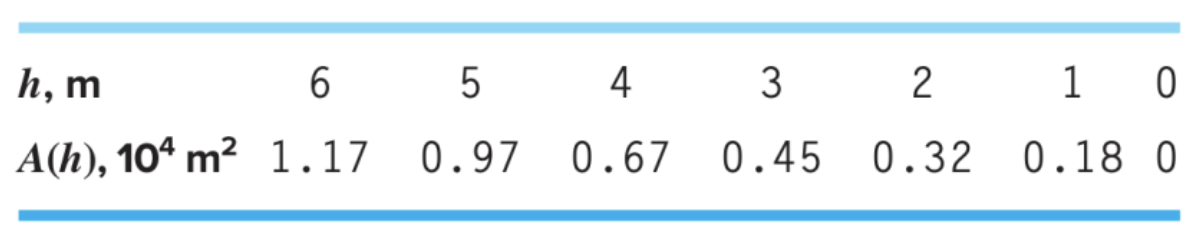

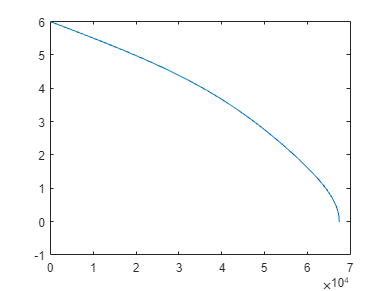

% Step 1: Setup
d = 0.25;
e = 1;
g = 9.81;

h = [6 5 4 3 2 1 0];
a = 10.^4 .* [1.17 0.97 0.67 0.45 0.32 0.18 0];

p = polyfit(h, a, 6);  % n-1
func = @(t, h) ( - (pi .* d.^2 ) ./ ( 4 .* ( polyval(p,h) ) )  .* (sqrt(2.*g.*(h+e))));

% Euler's to solve ODEs
i = 0;
hstep = 0.1;
t(1) = 0;
while 1
    i = i + 1;
    t(i+1) = t(i) + hstep;    % Increase time
    h(i+1) = h(i) + (func( t(i), h(i)) .* hstep);    % Use Euler's method or something else.
    if h(end) < 0 || imag(h(end)) > 0     % If the solution becomes negative or not real break the loop.
        break
    end
end
plot(t,h)

disp(['Time to drain is approximately t = ',num2str(t(end)),' seconds or ',num2str(t(end)/3600),' hours.'])

Time to drain is approximately t = 67455.4 seconds or 18.7376 hours.


functions

function [answ] = eulerOde(y0, h, tstart, tend, eq)
% y0 is y at t = 0 (given)
% tstart is start t
% tend is end t
% h is step size
% eq is given equation in syms with y and t as variables
    y1 = y0;
    yArr = [];
    yArr(2,1) = y0;
    for n = tstart:h:(tend-h)
        syms y t
        ynew = y1 + subs(eq, [y, t], [y1, n])*h;
        yArr(2,end+1) = ynew;
        y1 = double(ynew);
    end
    yArr(1,1) = y1;
    answ = yArr;
end

% Heuns ODE without iteration
function [answ] = heunsOde(y0, h, tstart, tend, eq)
% y0 is y at t = 0 (given)
% tstart is start t
% tend is end t
% h is step size
% eq is given equation in syms
    y1 = y0;
    yArr = [];
    yArr(2,1) = y0;
    for n = tstart:h:(tend-h)
        syms y t
        ynew = y1 + subs(eq, [y, t], [y1, n])*h;
        y1 = double(y1 + (subs(eq, [y, t], [y1, n]) + subs(eq, [y, t], [ynew, n + h]))/2 * h);
        yArr(2,end+1) = y1;
    end
    yArr(1,1) = double(y1);
    answ = yArr;
end

% Heuns ODE with iteration
function y_array = HeunIterativeMethod(init, start, final, step, dy, tol)

t = start:step:final;
y_array =  [ init ]; 

    for j = 1:length(t)-1
        init_slope = dy(t(j),y_array(j));  % first initial slope
        init_next_y = y_array(j) + ( init_slope * step );   % first predicted y-val.
        iter = 0;
        while iter < 100
            next_slope = dy(t(j)+step,init_next_y);   % slope at first predicted y-val
            avg_slope = ( init_slope + next_slope )/2;   % average of initial slope and slope at firstly predicted y-val. 
            new_next_y = y_array(j) + ( avg_slope * step ); % newly predicted y-val.
            err = ( abs(( new_next_y - init_next_y ) / new_next_y ) ) * 100;  % comparing the relative error between two predicted y.
            if err < tol          % if the error is lower than the tolerance,
                y_array(end+1) = new_next_y;    % the newly predicted y becomes the approximation, adding it to the array.
                break
            else                  % or else, the newly predicted y become the first predicted y-val.
                init_next_y = new_next_y;
                iter = iter + 1;
            end
        end
        disp(iter)
    end
end

% function for Runge - Kutta (RK) Method
function [y_values] = rungeKutta4(yInitial, h, t_start, t_end, ode_equation)
    % Initialize arrays to store time and y values
    t_values = t_start:h:t_end;
    y_values = zeros(size(t_values));
    
    % Set the initial value
    y_values(1) = yInitial;

    % Perform the Runge-Kutta integration
    for n = 1:(length(t_values) - 1)
        tt = t_values(n);
        yy = y_values(n);
        % Calculate the four slopes (k1, k2, k3, k4)
        syms y t
        k1 = h * subs(ode_equation, [t, y], [tt, yy]);
        k2 = h * subs(ode_equation, [t, y], [tt + h/2, yy + k1/2]);
        k3 = h * subs(ode_equation, [t, y], [tt + h/2, yy + k2/2]);
        k4 = h * subs(ode_equation, [t, y], [tt + h, yy + k3]);
        
        % Update y using the weighted average of the slopes
        y_values(n + 1) = yy + (k1 + 2*k2 + 2*k3 + k4)/6;
    end
end